# ACO Assignment 2022 Q3 H Infinity Controller

## Load Linearized State-space plant

clc 
clear 
load linearizedModel_Outputs.mat


## Define some variables for use

s = zpk('s') %for defining transfer functions

s =
 
  s
 
Continuous-time zero/pole/gain model.



om_rad = logspace(-2,5,1001); %define logspace range for plotting bode plot
om_rad_lin = linspace(0.5,3,1001); %define range for plotting highlight of frequency range

bw_gamma_rad = 0.2*2*pi %define target azimuth motion bandwith, 2pi radians is one hertz

bw_gamma_rad = 1.2566

bw_alpha_rad = 0.25*2*pi %define target elevation motion bandwith, 2pi radians is one hertz

bw_alpha_rad = 1.5708

##  Look at the plant

% figure(1)
% bode(P_ss_self, om_rad)
% grid on


## Singular Value

% figure(2)
% subplot(1,2,1)
% sigma(P_ss_self,om_rad)
% legend
% grid on
% subplot(1,2,2)
% sigma(P_ss_self,om_rad_lin)
% legend
% grid on

% rng(0,'twister'); % For reproducibility
% H = rss(4,2,3);
% bode(H)
% grid on
% sigma(H)
% legend
% grid on

## Design the weights individually then combine them

%Penalize high frequency input from the actuator
W_Vgamma = 1;%same importance, no bandwidth limit for control signal, yet
W_Valpha = 1;%same importance

Wi =mdiag(W_Vgamma,W_Valpha);
Wi = ss(Wi);

Wo11 = 20e-2/(s + 6*bw_gamma_rad);%1*bw_gamma_rad
Wo22 = 40e-2/(s + 6*bw_alpha_rad); %0.1*bw_alpha_rad
Wo = mdiag(Wo11,Wo22);
Wo = ss(Wo);


## Form the Weighted Plant

Pw = Wo*P_ss_self*Wi;

## Check the weighted plant with sigma

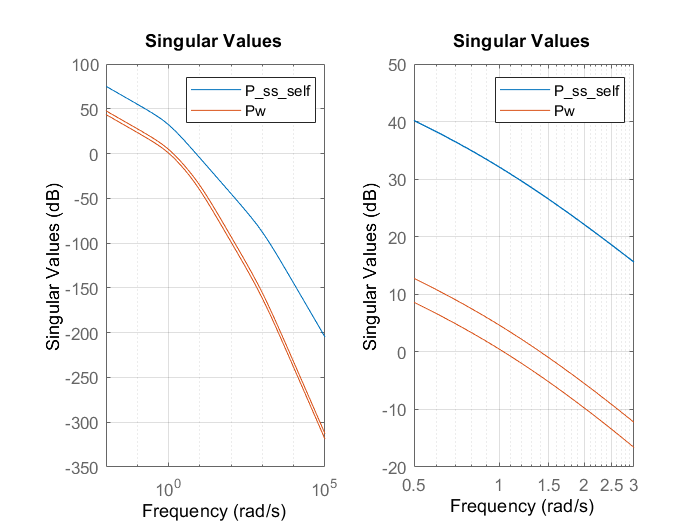

figure(3)
clf
subplot(1,2,1)
sigma(P_ss_self,Pw,om_rad)
legend
grid on
subplot(1,2,2)
sigma(P_ss_self,Pw,om_rad_lin)
legend
grid on

## Check the weight plant with bode

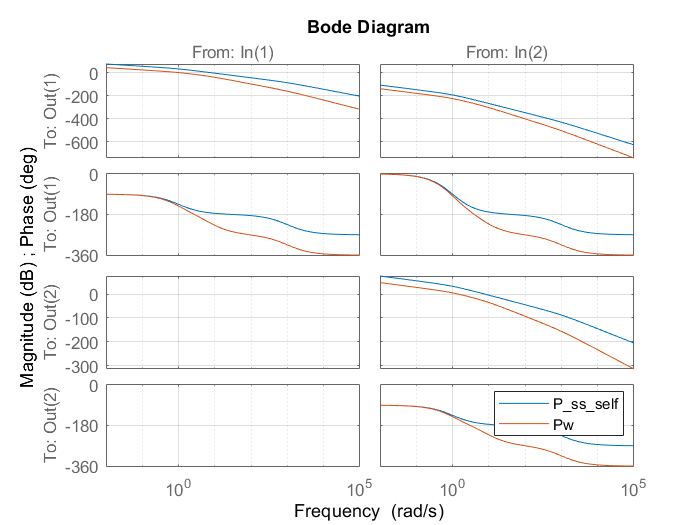

figure(4)
bode(P_ss_self,Pw,om_rad)

legend
grid on

## Check the robustness with rho, v-gap

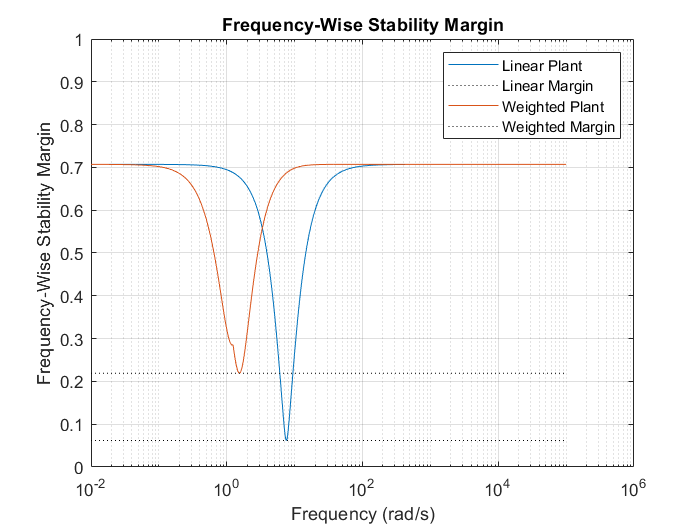

figure(5)
clf
rho(P_ss_self, -eye(2),om_rad)
hold on
rho(Pw, -eye(2),om_rad)
grid on
legend('Linear Plant','Linear Margin','Weighted Plant','Weighted Margin')
hold off

## Check robustness with multiloop input output diskmargin

[~,MM_P] = diskmargin(P_ss_self)

MM_P = struct with fields:
           GainMargin: [0.8832 1.1322]
          PhaseMargin: [-7.0982 7.0982]
           DiskMargin: 0.1240
           LowerBound: 0.1240
           UpperBound: 0.1243
            Frequency: 7.5556
    WorstPerturbation: [2×2 ss]


% DGM_P_alpha = DM_P(2).GainMargin;
% DGM_P_gamma = DM_P(1).GainMargin;

% DGMAll_P = [DGM_P_gamma;DGM_P_alpha];
DGM_P = MM_P.GainMargin;

[~,MM_Pw] = diskmargin(Pw)

MM_Pw = struct with fields:
           GainMargin: [0.6338 1.5777]
          PhaseMargin: [-25.2647 25.2647]
           DiskMargin: 0.4482
           LowerBound: 0.4482
           UpperBound: 0.4491
            Frequency: 1.5348
    WorstPerturbation: [2×2 ss]


% DGM_Pw_alpha = DM_Pw(2).GainMargin
% DGM_Pw_gamma = DM_Pw(1).GainMargin

% DGMAll_Pw = [DGM_Pw_gamma;DGM_Pw_alpha];
DGM_Pw = MM_Pw.GainMargin;

## Plot the diskmargins

figure(6)
clf
t6 = tiledlayout(1,2,'TileSpacing','Compact');
ax6a = nexttile

ax6a =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


diskmarginplot(DGM_P,'disk')

ax6b = nexttile

ax6b =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3375]
            Units: 'normalized'

  Show all properties


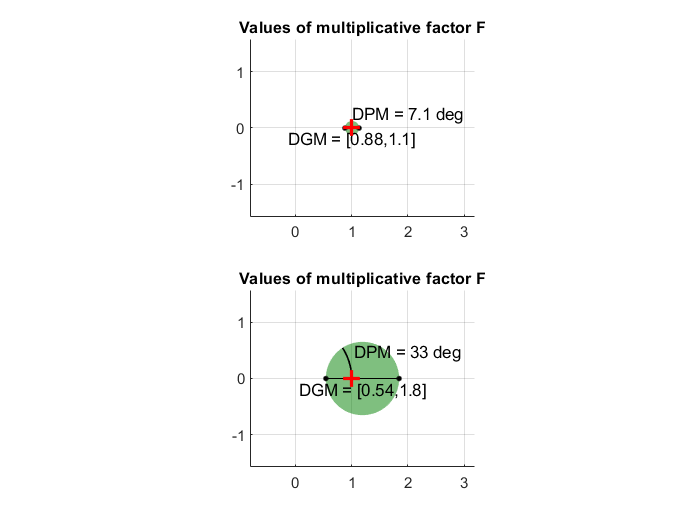

diskmarginplot(DGM_Pw,'disk')
linkaxes([ax6a,ax6b],'x')
linkaxes([ax6a,ax6b],'y')
% 
t6title = {'MIMO I/O Disk Margin','Left: Linear Plant, Right: Weighted Plant'};
% 
% title(t6,{t6title})

title(t6,t6title)

%% 
figure(7)
clf
t = tiledlayout(2,2,'TileSpacing','Compact');

nexttile
diskmarginplot(DGM_P_gamma,'nyquist')
nexttile
diskmarginplot(DGM_P_alpha,'nyquist')
nexttile
diskmarginplot(DGM_Pw_gamma,'nyquist')
nexttile
diskmarginplot(DGM_Pw_alpha,'nyquist')
title(t,{'Disk Margin for robustness within region of uncertainty','First Column: Azimuth Voltage to '})

